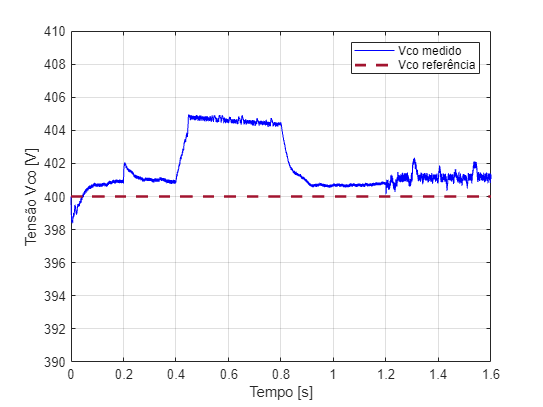

load("resultados Silvia.mat")


Vco = out.Vok.signals(1).values;
Vco_ref = out.Vok.signals(2).values;
ILs = out.ILsk.signals(1).values;
ILs_ref = out.ILsk.signals(2).values;
ILb = out.ILbk.signals(1).values;
ILb_ref = out.ILbk.signals(2).values;
rok = out.Rok.signals(1).values;
rok_ref = out.Rok.signals(2).values;
t = linspace(0,1.6,length(Vco));

plot(t,Vco,"Color","b","DisplayName","Vco medido")
hold on
plot(t,Vco_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","Vco referência")
hold off
xlabel("Tempo [s]")
ylabel("Tensão Vco [V]")
axis([0 1.6 390 410])
legend
grid

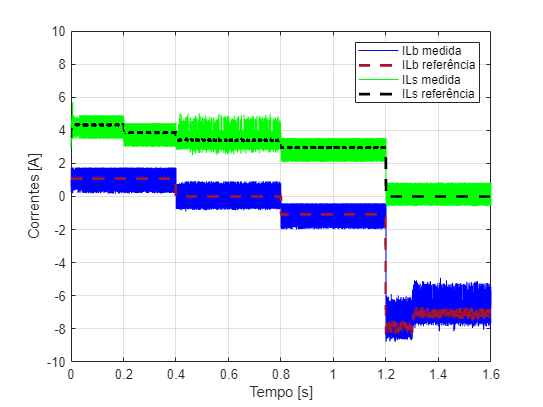



plot(t,ILb,"Color","b","DisplayName","ILb medida")
hold on
plot(t,ILb_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","ILb referência")
plot(t,ILs,"Color"," g","DisplayName","ILs medida")
plot(t,ILs_ref,'--','LineWidth',2,"Color","#000000","DisplayName","ILs referência")
hold off
xlabel("Tempo [s]")
ylabel("Correntes [A]")
axis([0 1.6 -10 10])
legend
grid

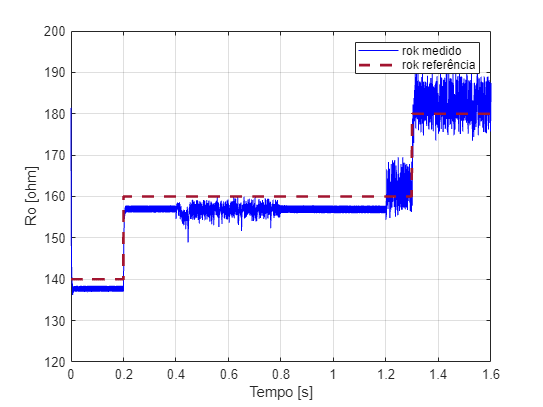


plot(t,rok,"Color","b","DisplayName","rok medido")
hold on
plot(t, rok_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","rok referência")
hold off
xlabel("Tempo [s]")
ylabel("Ro [ohm]")
axis([0 1.6 120 200])
legend
grid


m1 = Vco(1:40000);
m2 = Vco(40001:80000);
m3 = Vco(80001:120000);
m4 = Vco(120001:160000);
d1 = peak2peak(Vco(1:40000));
d2 = peak2peak(Vco(40001:80000));
d3 = peak2peak(Vco(80001:120000));
d4 = peak2peak(Vco(120001:160000));

disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("400  " +mean(m1)+ "  "+ 100*(mean(m1) - 400)/400 + "  " + d1+ " " + (400 - max(m1)))

400  400.7681  0.19203  3.6715 -2.0554


disp("400  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2+ " " + (400 - max(m2)))

400  404.3931  1.0983  4.0788 -4.9458


disp("400  " +mean(m3)+ "  "+ 100*(mean(m3) - 400)/400 + "  " + d3+ " " + (400 - max(m3)))

400  400.9996  0.2499  3.925 -4.4611


disp("400  " +mean(m4)+ "  "+ 100*(mean(m4) - 400)/400 + "  " + d4+ " " + (400 - max(m4)))

400  401.1211  0.28029  2.2101 -2.3403


% 
% 

i1 = rok(5000:20000);
i2 = rok(25000:120000);
i3 = rok(135001:160000);
d1 = peak2peak(rok(5000:20000));
d2 = peak2peak(rok(25001:120000));
d3 = peak2peak(rok(135001:160000));


disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("140  " +mean(i1)+ "  "+ 100*(mean(i1) - 140)/140 + "  " + d1)

140  137.4781  -1.8014  1.4684


disp("160  " +mean(i2)+ "  "+ 100*(mean(i2) - 160)/160 + "  " + d2)

160  156.5682  -2.1449  11.1277


disp("180  " +mean(i3)+ "  "+ 100*(mean(i3) - 180)/180 + "  " + d3)

180  183.0643  1.7024  19.7853
